% function [cov_matrix, ev1, ev2] = cov_analysis(raster_data, stimulus, window, P.fs)
% 
start_stim = P.OFF_dur *P.fs;
stop_stim = (P.OFF_dur +P.ON_dur) * P.fs;

raster_data = P(1).raster(:,start_stim:stop_stim-1);
stimulus = -P(1).antennal_movement(:,start_stim:stop_stim-1);
% stimulus = P(1).stim_ifb(:,start_stim:stop_stim-1);
% intendedStimulus = stim.data.load;
% stimulus = intendedStimulus(start_stim:stop_stim-1,:)';

% stimulus_model = stimulus(:,1:8*fs);
% raster_data_model = raster_data(:,1:8*fs);
stimulus_model = stimulus;
raster_data_model = raster_data;


% stimulus = stimulus - mean(stimulus,2);

% raster_data = WN_Repeat_Matrix';
% stimulus = wn_stim_matrix';
stim_window = 0.05;
nTrials = size(raster_data_model,1);
% P.fs = 8e4;

[NstimPriors,~] = size(raster_data_model);
STA_freq = [];
numSpikes = sum(raster_data_model,'all');
all_spike_triggers = nan([numSpikes stim_window*P.fs+1]);
k=1;
spike_triggers = [];

for i=1:NstimPriors
    spike_locs = find(raster_data_model(i,:)==1);
    if isempty(spike_locs)
        continue;
    end
    for j=1:length(spike_locs)
        if (spike_locs(j)-stim_window*P.fs)>= 0
            
            spike_triggers = stimulus_model(i,(spike_locs(j)-stim_window*P.fs):spike_locs(j));
%             spike_triggers = spike_triggers-mean(spike_triggers);
            %             plot(STA); hold on;
%             all_spike_triggers = [all_spike_triggers; spike_triggers];
            all_spike_triggers(k,:) = spike_triggers;
            k=k+1;
        end
    end

end
TF=isnan(all_spike_triggers(:,1));
all_spike_triggers(TF,:)=[];


## Prior covariance matrix

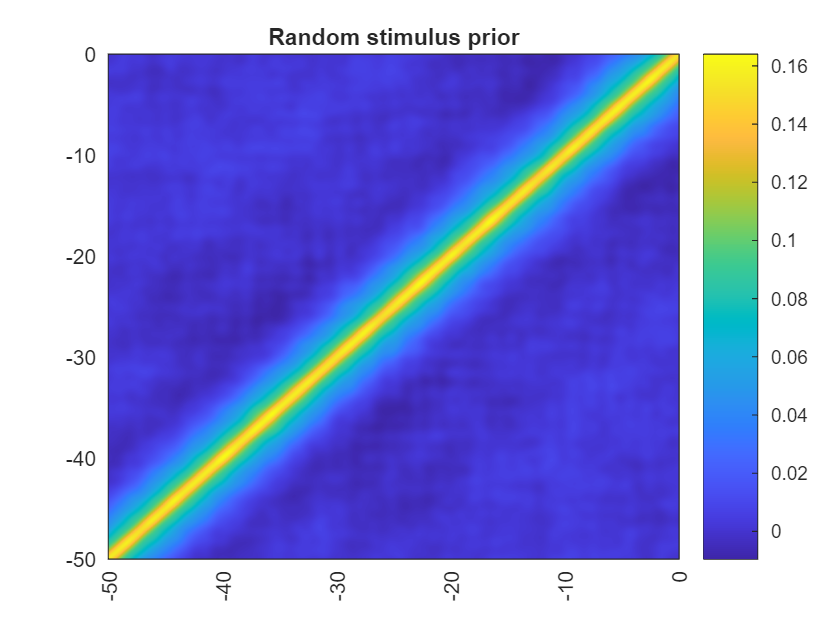

pattern_length = size(all_spike_triggers,2);
NstimPriors = size(all_spike_triggers,1);
stimulus_prior = zeros([NstimPriors pattern_length]);
r = randi([1 (length(stimulus_model)-pattern_length)],1,NstimPriors);
for j=1:NstimPriors
    stimulus_prior(j,:) = stimulus_model(randperm(size(stimulus_model,1),1),r(j):r(j)+pattern_length-1);
end

avg_stim = mean(stimulus_prior,1);
stim_prior_cov = cov(stimulus_prior-avg_stim);
% stim_prior_cov = (1/(NstimPriors -1))*(stimulus_prior-avg_stim)'*(stimulus_prior-avg_stim);
figure;
h = heatmap((stim_prior_cov), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-stim_window*1e3,0,length(stim_prior_cov));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Random stimulus prior");

## Calculating STA

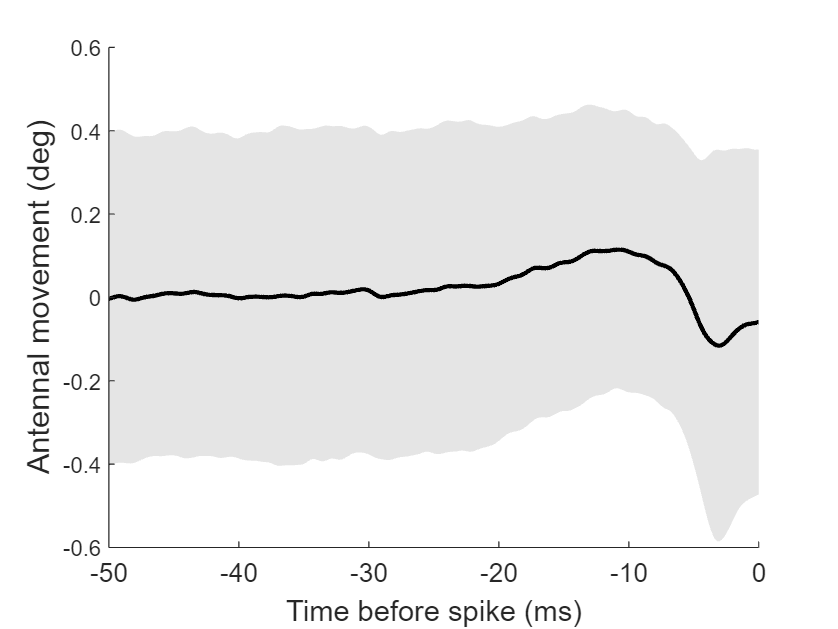

% STA_ = mean(all_spike_triggers,1);
STA = mean(all_spike_triggers-avg_stim,1); %% Subtracting mean of all stimulus patterns
t= linspace(-stim_window*1000, 0, length(STA));
figure;
% plot(t,STA_); hold on;
% plot(t, STA);
% confintervalplot(t, size(all_spike_triggers,1), STA, std(all_spike_triggers-avg_stim,0,1), 0.95);
% hold on;
% [lineOut, ~] = stdshade(all_spike_triggers - avg_stim, 0.1, 'k');
% lineOut.LineWidth = 2;
sdfill(t, mean(all_spike_triggers,1), std(all_spike_triggers,0,1));
% title('Spike Triggered Average');
% title(join([expt_date replace(P.filename, "_", "-")]," "));
xlabel('Time before spike (ms)','FontSize',12);
ylabel('Antennal movement (deg)','FontSize',12);
% legend('STA without avg stimulus subtracted', 'Avg stimulus subtracted', 'Location','best')
ax = gca;
ax.XAxis.FontSize = 12;
ax.XLabel.FontSize = 14;
ax.YLabel.FontSize = 14;
ax.XAxis.FontSize = 12;
ax.Box = "off";


nspikes = size(all_spike_triggers,1);
cov_matrix = cov(all_spike_triggers-STA);
% cov_matrix = (1/(nspikes -1))*(all_spike_triggers-STA)'*(all_spike_triggers-STA);
% cov_matrix = (1/(nspikes -1))*((all_spike_triggers'*all_spike_triggers)-(STA'*STA));

figure;

h = heatmap((cov_matrix), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-stim_window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Spike Triggered Covariance (STC)");

## Null distribution of eigen values

nPatterns = nspikes;
rand_stim = zeros([nPatterns pattern_length]);
Ds_null = [];

for repeats = 1:1000
    rr = randi([1 (length(stimulus_model)-pattern_length)],1,nPatterns);
    for j=1:nPatterns
        rand_stim(j,:) = stimulus_model(randperm(size(stimulus_model,1),1),rr(j):rr(j)+pattern_length-1);
    end
    fig_handle
    random_cov = cov(rand_stim-STA);
    
    [V,D] = eig(random_cov-stim_prior_cov);
    % [V,D] = eig(cov_matrix);
    Ds_null= [Ds_null diag(D)];
end

[~, ind] = sort(real(Ds_null), 'descend');
% [~, ind] = sort(real(diag(D)), 'descend');


figure;
plot(sort(real(Ds_null),'ascend'), '.',"MarkerSize",20);
% plot(sort(real(eVal),'descend'))
title('Eigen values of null distribution');
ylabel('Eigen values');
xlabel('Index');
ax = gca;
ax.Box = "off";

min_null = min(Ds_null, [], 'all');
max_null = max(Ds_null, [], 'all');

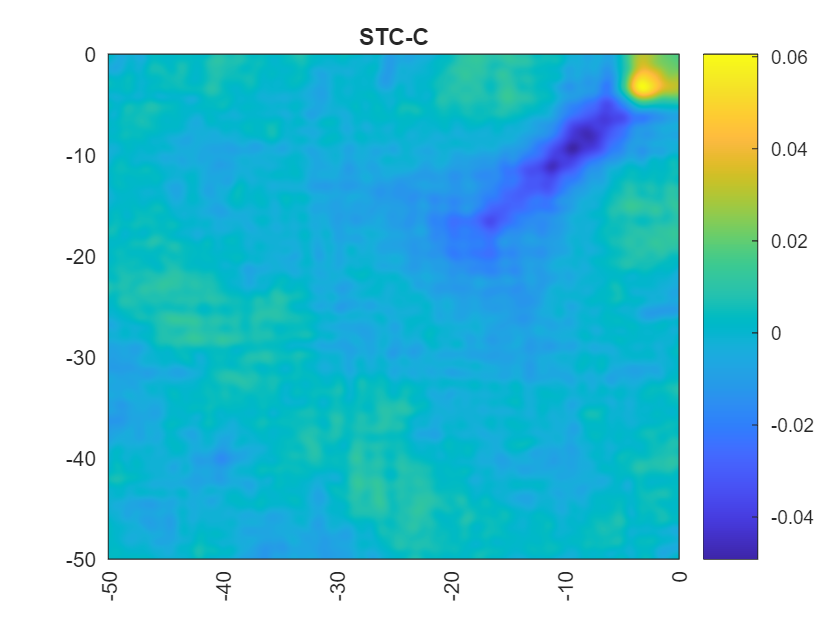

diff_cov = (cov_matrix - stim_prior_cov) ; 
figure;
h = heatmap(diff_cov, 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-stim_window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("STC-C");


% for i=1:3
%     figure;
%     plot(t, diff_cov(i,:));
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end


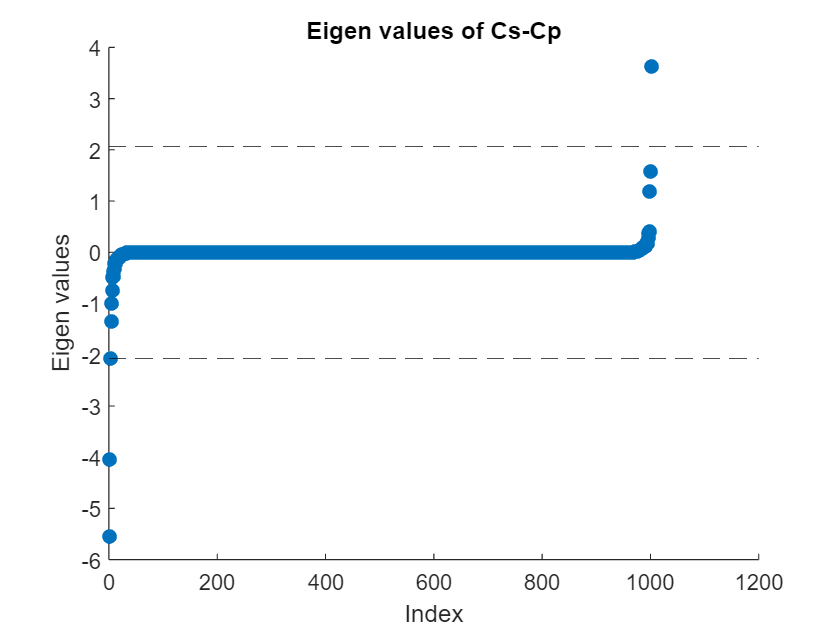


[V,D] = eig(diff_cov);
% [V,D] = eig(cov_matrix);

[~, ind] = sort(abs(real(diag(D))), 'descend');
% [~, ind] = sort(real(diag(D)), 'descend');
Ds = D(ind,ind);
Vs = V(:,ind);

eVal = diag(Ds);

% Significant Eigen values
eVal_sig_ind = find(eVal < min_null | eVal > max_null);
eVal_sig = eVal(eVal_sig_ind);

sig_evec = Vs(:,eVal_sig_ind);

% eVec1 = Vs(:,1);
% eVec2 = Vs(:,2);
% eVec3 = Vs(:,3);
% eVec4 = Vs(:,4);

figure;
plot(sort(real(diag(D)),'ascend'), '.',"MarkerSize",20); hold on;
yline(min_null, '--k');
yline(max_null, '--k');
title('Eigen values of Cs-Cp');
ylabel('Eigen values');
xlabel('Index');
ax = gca;
ax.Box = "off";

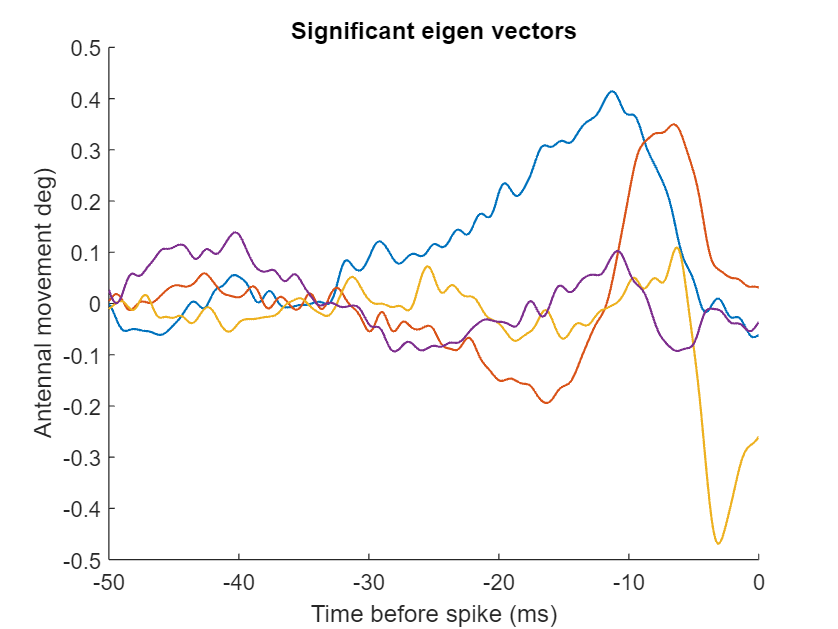



t= linspace(-stim_window*1000, 0, length(STA));

figure;

hold on;
% plot(t,Vs(:,1)*eVal(1),'LineWidth',1); 
% plot(t,Vs(:,2)*eVal(2),'LineWidth',1);
% plot(t,Vs(:,3)*eVal(3),'LineWidth',1);
% plot(t,Vs(:,4)*eVal(4),'LineWidth',1);
for val_ind=1:length(eVal_sig)
    plot(t,sig_evec(:,val_ind)*eVal_sig(val_ind), 'LineWidth',1);
end
ylabel('Antennal movement (mm)');
% plot(t,sum(Vs(:,1:2),2));
% yyaxis right; plot(t,STA); ylabel("STA");
% legend("EV1","EV2","Sum of EVs", "STA", 'Location',"best");
% plot(t,Vs(:,1:2));
ax = gca;
% ax.YAxis.Visible = 'off'
ax.Box = 'off';

% legend("STA","EV1","EV2");
title('Significant eigen vectors');
xlabel('Time before spike (ms)');
ylabel('Antennal movement deg)');


% figure;
% plot(60*diff(Vs(:,2))); hold on;
% plot(Vs(:,1));

% corrcoef(STA, eVec1)
% corrcoef(eVec2+eVec1,STA)


## Orthogonalize eigen vectors

sig_evec_orth = [];
for i = 1:length(eVal_sig)
    sig_evec_orth(:,i) = sig_evec(:,i) -  ((dot(sig_evec(:,i), STA)/(norm(STA))^2)*STA');    
end

% eVec1_orth = eVec1 - ((dot(eVec1, STA)/(norm(STA))^2)*STA');
% eVec2_orth = eVec2 - ((dot(eVec2, STA)/(norm(STA))^2)*STA');
% eVec3_orth = eVec3 - ((dot(eVec3, STA)/(norm(STA))^2)*STA');
% eVec4_orth = eVec4 - ((dot(eVec4, STA)/(norm(STA))^2)*STA');
% figure; plot(eVec1); hold on; plot(eVec1_orth); plot(eVec2); plot(eVec2_orth);

## Differential of Eigen vector

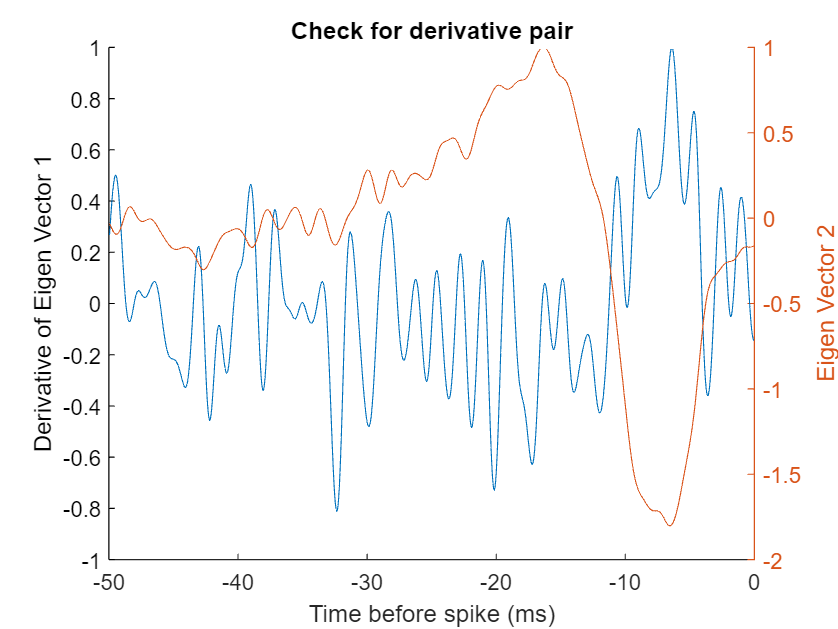

diffEVec1Norm = diff(sig_evec(:,1))/max(diff(sig_evec(:,1)));
eVec2Norm = sig_evec(:,2)/max(sig_evec(:,2));
figure;
plot(t(2:end), diffEVec1Norm); hold on;
ylabel('Derivative of Eigen Vector 1');
yyaxis right; plot(t(2:end), eVec2Norm(2:end));
ylabel('Eigen Vector 2');
xlabel('Time before spike (ms)');
ax=gca;
ax.Box = 'off';
title("Check for derivative pair")

% legend("d/dt (Eigen Vector 1)", "Eigen Vector 2","Location","best");

% figure;
% plot(diff(eVec1)); hold on;
% yyaxis right; plot(-eVec2);
% legend("d/dt (Eigen Vector 1)", "-Eigen Vector 2","Location","best");

% corrcoef(diffEVec1Norm,eVec2Norm(2:end))